# Generador de funciones

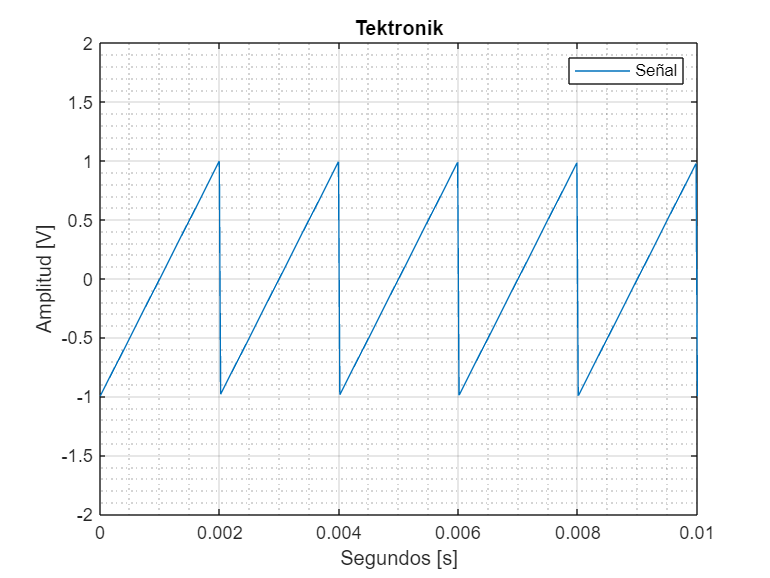

clear; clc;
Fs = 44.1e3;
t = linspace(0,1,Fs);
f = 500;
w = 2*pi*f;
duty = 50;
m = 1;
signal = "triangular";
 
if signal == "sine"
    y  = sin(w*t);
elseif signal == "square"
    y = square(w*t,duty);
else
    y = sawtooth(w*t,m);
end
figure(1);
plot(t,y,"DisplayName",signal);
grid on; grid minor;
xlabel("Segundos [s]"); ylabel("Amplitud [V]");
title("Tektronik");
legend(); axis([0 1/100 -2 2]);

sound(y,Fs)
 